# Script teste da função minhaHorner

%teste x escalar
a=[3 2 1 5];
x=0.5

x = 0.5000

valorPol= minhaHorner(a,x)

valorPol = 6.3750

%testa x vetor
x=-2:0.1:2;
vetorPol= minhaHorner(a,x);

%testar contra benchmark
tic
disp(length(x));

    41



q=polyval(a,x);
toc

Elapsed time is 0.013010 seconds.


tic
nosso=minhaHorner(a,x);
toc

Elapsed time is 0.006156 seconds.


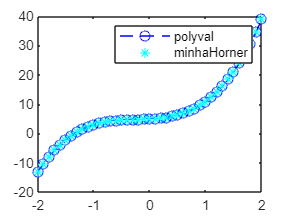

q=polyval(a,x);
nosso=minhaHorner(a,x);
plot(x,q,'b--o')
hold on
plot(x,nosso,'c*')
hold off
legend('polyval','minhaHorner')